clear;

Fs=20000;

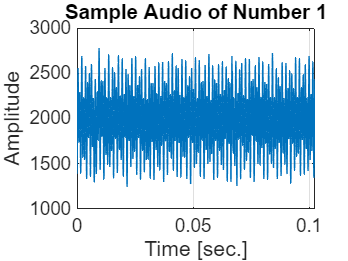

% Plot Time Domain Sine Signal (input_signal)


fid = fopen('fft_buffer.bin'); % put the correct file name
signal = fread(fid,inf,'float'); 
fclose(fid);

time=[1:length(signal)]/Fs;

figure; 
plot(time,signal,'LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlabel('Time [sec.]','FontSize',16);
ylabel('Amplitude','FontSize',16);  
title('Sample Audio of Number 1');  % This is the title of the plot (modify for each different plot)

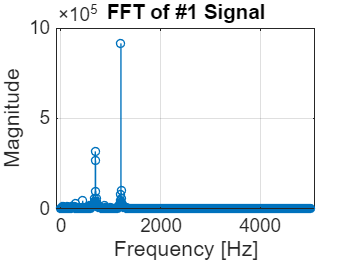

% Plot output_fft vs output_freq
% arm_rfft_fast_f32 calculates complex fft of the signal with a length of
% FFT_LENGTH
% odd elements of the array are real components - even elements are imag
% components.
% We need to find the magnitude of each complex number before plot.


fid = fopen('output_fft.bin'); % put the correct file name
spectrum = fread(fid,inf,'float'); 
fclose(fid);

fid = fopen('output_freq.bin'); % put the correct file name
freq = fread(fid,inf,'float'); 
fclose(fid);

real_spectrum = spectrum(1:2:end);
imag_spectrum = spectrum(2:2:end);
mag_spectrum = sqrt(real_spectrum.^2 + imag_spectrum.^2);


figure; 
stem(freq(2:end,:),mag_spectrum(2:end,:),'LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlabel('Frequency [Hz]','FontSize',16);
ylabel('Magnitude','FontSize',16);  
title('FFT of #1 Signal');  % This is the title of the plot (modify for each different plot)

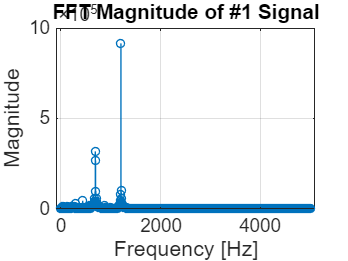

% Plot output_fft_mag vs output_freq
% arm_cmplx_mag_f32 calculates complex mag. fft of the signal with a length of
% FFT_LENGTH/2

fid = fopen('output_fft_mag.bin'); % put the correct file name
spectrum = fread(fid,inf,'float'); 
fclose(fid);

fid = fopen('output_freq.bin'); % put the correct file name
freq = fread(fid,inf,'float'); 
fclose(fid);

figure; 
stem(freq(2:end,:),spectrum(2:end,:),'LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlabel('Frequency [Hz]','FontSize',16);
ylabel('Magnitude','FontSize',16);  
title('FFT Magnitude of #1 Signal');  % This is the title of the plot (modify for each different plot)